% Jep Brinkmann Thesis HMM example
clc; close all;

k = 4;
d = 20;

lam = 5;

T = lam * eye(k) + abs(randn(k, k));
T = Stochasticize(T);

O = initialize_emission_matrix(d, k, 1);


k = 3;
d = 8;

T = [8/10, 1/15, 1/6;
    1/10, 13/15, 1/6; 
    1/10, 1/15, 2/3];

O = [6/15, 1/20, 1/50;
    1/15, 11/20, 1/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 21/50;
    1/15, 1/20, 21/50;
    1/15, 1/20, 1/50;
    1/15, 1/20, 1/50;
    3/15, 3/20, 3/50;];


pi = findStationaryDistribution(T');

U{1} = Stochasticize(O * diag(pi) * T' / inv(diag(T * pi')));
U{2} = O;
U{3} = (O * T);

P3 = cpdgen(U)/k;

Taug = [0, pi; zeros(k, 1), T'];
Oaug = [zeros(1, d); O'];




rho = 0.95;
epsilon = 1e-6;
nIter = 10;

T_seq = 1e8;
alpha = 1e-6;

csls = khatri_rao([1e6 1e7 1e8]', [1 2 3 4 5 6 7 8 9]');
N = length(csls);


error_P3_n = ones(N, 1);
error_P3_em = ones(N, 1);
error_P3_mle = ones(N, 1);

error_hmm_P3_n = ones(N, 1);
error_hmm_P3_em = ones(N, 1);
error_hmm_P3_mle = ones(N, 1);

for i = 1:N
    

    [seq,~] = hmmgenerate(csls(i), Taug, Oaug);
    
    [P3_n, T_seq_Error] = estimate_joint_prob(seq, d, P3);
    P3_em = EM_JPT_estimation(seq, d, rho, epsilon, nIter);
    P3_mle = laplacian_smoothing_mle(P3_n, alpha);

    error_P3_n(i) = norm(P3 - P3_n, "fro");
    error_P3_em(i) = norm(P3 - P3_em, "fro");
    error_P3_mle(i) = norm(P3 - P3_mle, "fro");
    
    [U_hat, ~] = cpd(P3_n,k);
    [T_hat, O_hat, pi_hat] = FactorMatrices2HMM(U_hat);
    [T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hat, pi_hat);
    error_hmm_P3_n(i) = norm(T-T_hat, "fro") + norm(O-O_hat, "fro") + norm(pi - pi_hat, "fro");
    
    [U_hat, ~] = cpd(P3_em,k);
    [T_hat, O_hat, pi_hat] = FactorMatrices2HMM(U_hat);
    [T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hat, pi_hat);
    error_hmm_P3_em(i) = norm(T-T_hat, "fro") + norm(O-O_hat, "fro") + norm(pi - pi_hat, "fro");
    
    [U_hat, ~] = cpd(P3_mle,k);
    [T_hat, O_hat, pi_hat] = FactorMatrices2HMM(U_hat);
    [T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hat, pi_hat);
    error_hmm_P3_mle(i) = norm(T-T_hat, "fro") + norm(O-O_hat, "fro") + norm(pi - pi_hat, "fro");

end


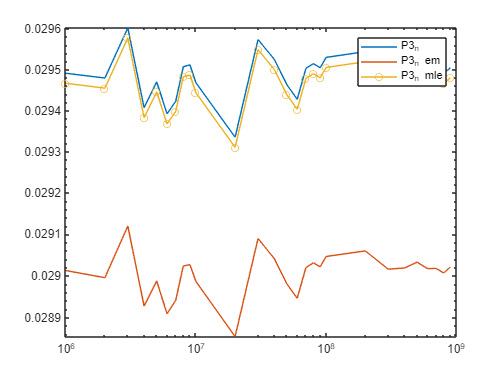


figure()
loglog(csls', error_P3_n', csls, error_P3_em', csls, error_P3_mle', 'o-')
legend('P3_n', 'P3_n em', 'P3_n mle')

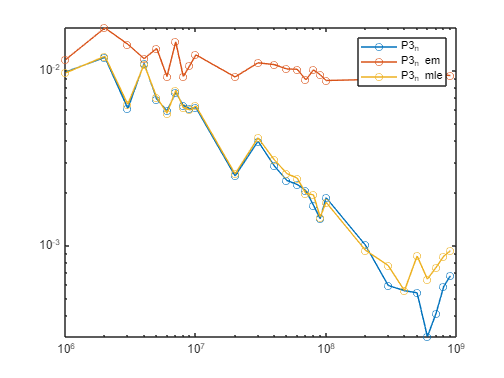



figure()
loglog(csls, error_hmm_P3_n, 'o-', csls, error_hmm_P3_em, 'o-', csls, error_hmm_P3_mle, 'o-')
legend('P3_n', 'P3_n em', 'P3_n mle')